close all
clear
clc

定义符号

syms z1 w n

计算sin的z变换，及其在z平面上的采样，X和Y分别是实部和虚部

z1 = ztrans(sin(n),w);
X = [-3:0.05:3];
Y = [-3:0.05:3];
Z = double(subs(z1,'w',log(exp(1j*Y')*exp(X))));

准备绘图

figure; hold on; grid off; axis off; box off;

选用表示“热”的色系，绘制z平面，限定显示区间

colormap(hot);
surf(X,Y,real(Z),'linestyle','none');
W = 4;
set(gca,'XLim',[-W W],'YLim',[-W W],'ZLim',[-W W]);
set(gca,'XTick',[],'YTick',[],'ZTick',[]);

生成太阳

R = 3;
ele = 60;
x = 0;
y = 0;
z = R*sin(ele*2*pi/360);
[sx,sy,sz] = sphere(30);

绘制太阳

hsun = surf(x+0.5*sx,y+0.5*sy,z+0.5*sz,10*ones(size(sz)));
set(hsun,'LineStyle','none');

生成光源，包括角度和颜色

hlight = lightangle(0,60);
set(hlight,'Color',[1 1 0.5]);

绘图，让太阳和视角（包括方位角和俯仰角）都旋转

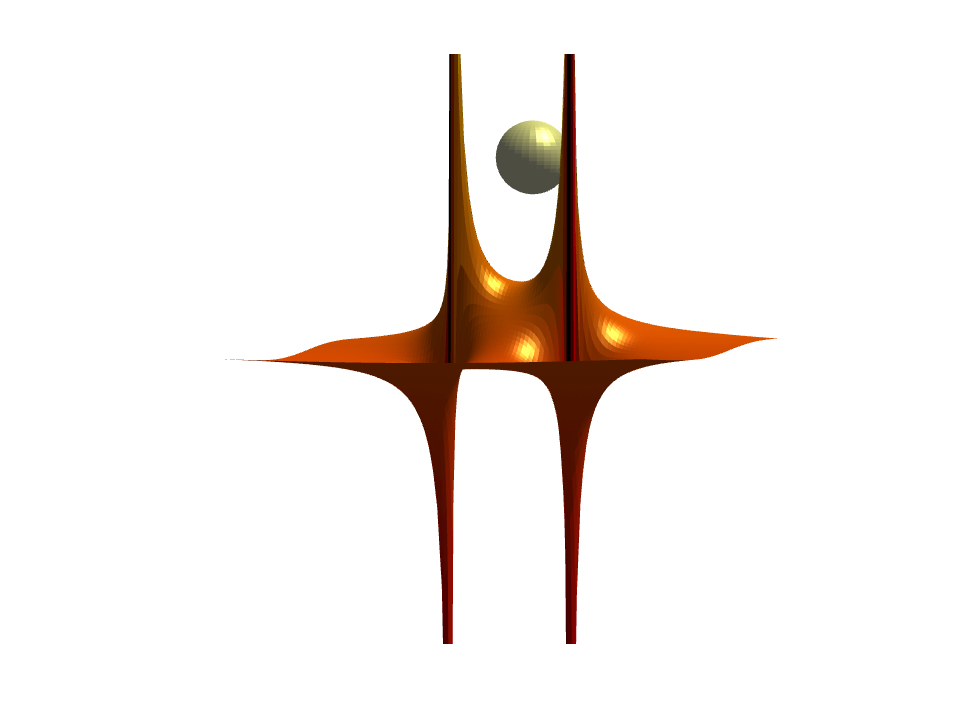

for n = 0:5:720
    lightangle(hlight,n,60);
    view(-0.1*n,40-40*n/720);
    x = R*cos(ele*2*pi/360)*cos((n)*2*pi/360);
    y = R*cos(ele*2*pi/360)*sin((n)*2*pi/360);
    set(hsun,'XData',x+0.5*sx,'YData',y+0.5*sy,'ZData',z+0.5*sz);
    pause(0.05);
end